# Kinematic model of Otbot

This live script develops the kinematic model of Otbot.

We start with a few initializations:

% Clear all variables, close all figures, and clear the command window
clearvars 
close all
clc

% Start stopwatch
tic

% Display the matrices with rectangular brackets
sympref('MatrixWithSquareBrackets',true);

%  Turn off abbreviated output format (avoid Matlab's own substitution of long expressions)
sympref('AbbreviateOutput',false); 

% Symbolic variables to be used (see the figures and explanations below)
syms l_1 l_2 r          % Pivot offset, semiaxis length, and wheel radius (constants)
syms theta theta_dot    % Absolute angular velocity of the chassis
syms v                  % Velocity of the chassis point M along direction 1'

syms varphi_dot_l       % Angular velocity of left wheel
syms varphi_dot_r       % Angular velocity of right wheel

syms a b                % Absolute coordinates of M
syms a_dot b_dot        % Absolute velocity components of M

syms x y                % Absolute coordinates of the pivot point P
syms x_dot y_dot        % Absolute velocity components of P
syms alpha alpha_dot    % Absolute angle and angular velocity of the platform

syms varphi_p           % Pivot angle
syms varphi_dot_p       % Angular velocity of the pivot joint

## Introduction to the robot

### Reference frames and vector bases

The following pictures describe the kinematic structure of Otbot:

        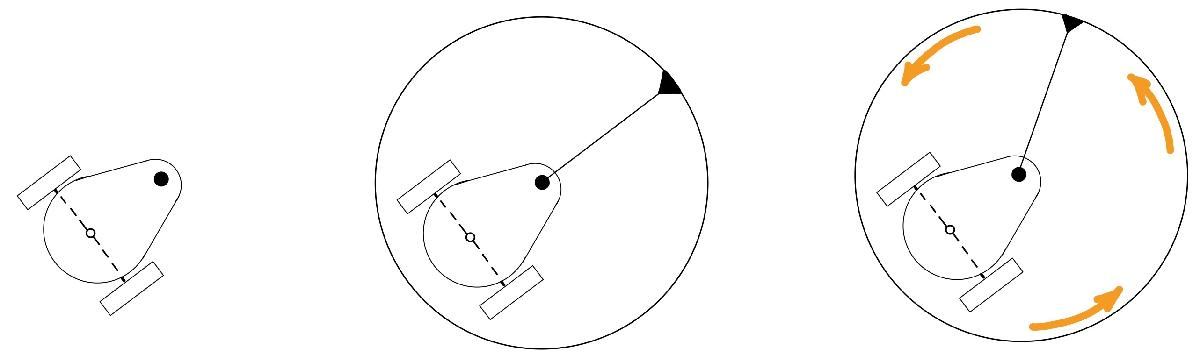

The robot chassis (left picture) is a classical differential drive robot whose two wheels are powered by DC motors. Passive caster wheels below the chassis (not drawn) impede the tumbling of the robot. A circular platform is mounted on top of the chassis (center picture) which can rotate relative to it (right picture). The rotation is performed by means of a pivot joint (black dot) that is controlled by another DC motor. Note that the pivot joint has an offset relative to the wheels' axis. This offset will allow the circular platform to behave like an omnidirectional vehicle in the plane.

To obtain the kinematic and dynamic models of the robot, we will use the following reference frames:

    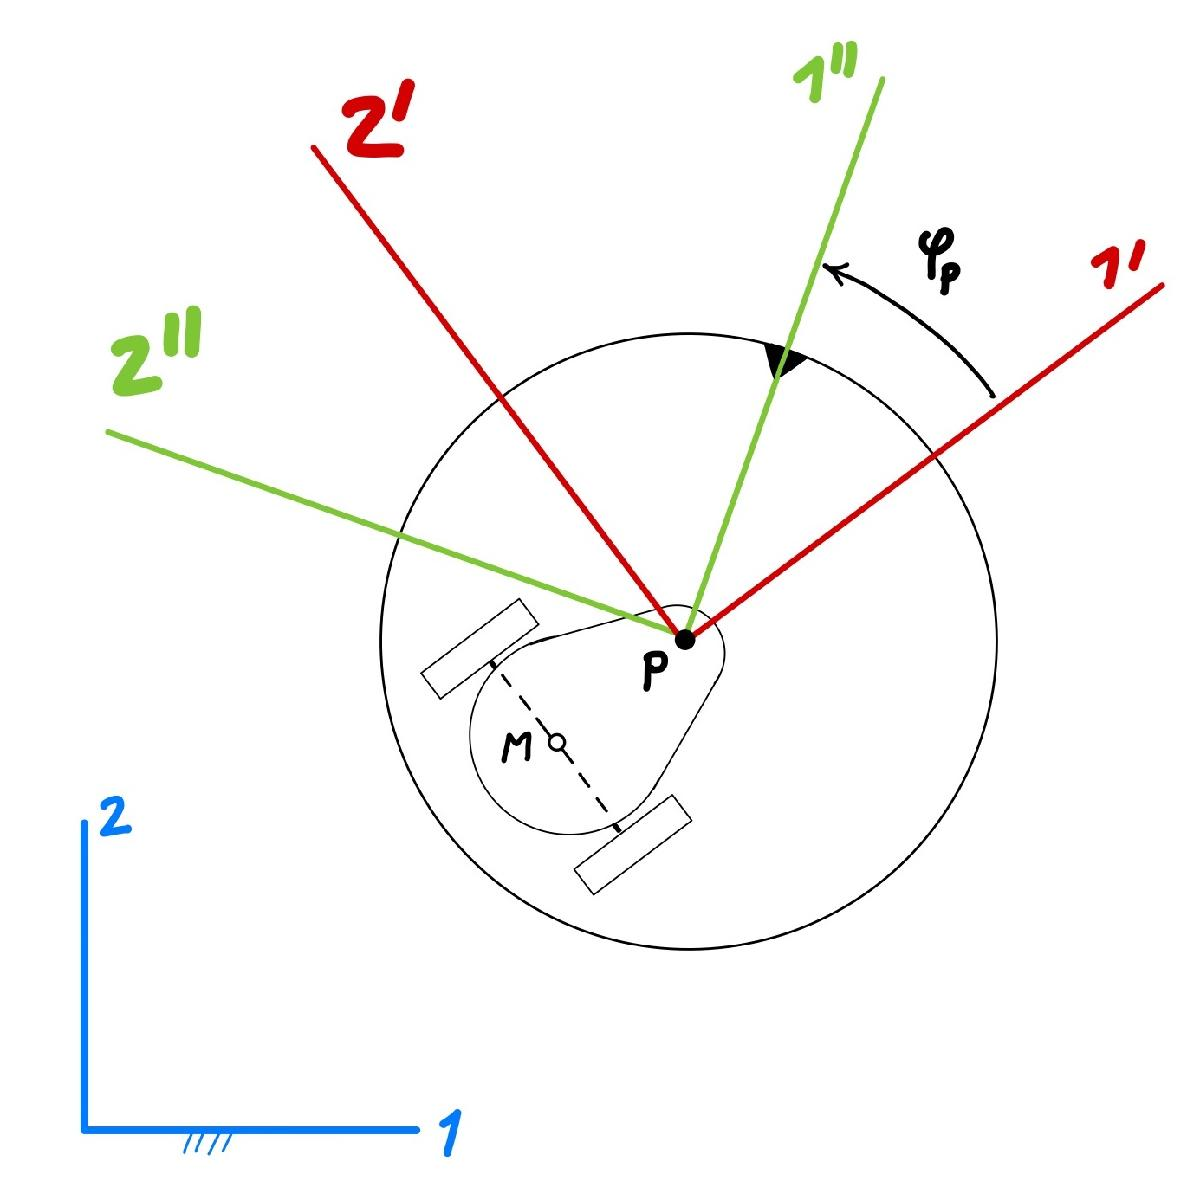  

The blue frame is the absolute frame fixed to the ground. The red and green frames are fixed to the chassis and the platform, respectively. Point M is the midpoint of the wheels axis and point P is the location of the pivot joint. The red axis 1' is always aligned with M and P. The angle between the green and red frames coincides with the pivot joint angle $\varphi_p$.

Each frame has a vector basis attached to it, whose unit vectors are directed along the frame axes. The three bases will be referred to as B = {1,2,3}, B' = {1', 2', 3'} and B" = {1", 2", 3"} respectively.

### Configuration and state coordinates

The robot configuration can be described by the following six coordinates: the absolute position $(x,y)$ of the pivot joint, the absolute angle $\alpha$ of the platform, the pivot angle $\varphi_p$, and the angles of the right and left wheels, $\varphi_r$ and $\varphi_l$, relative to the chassis. 

        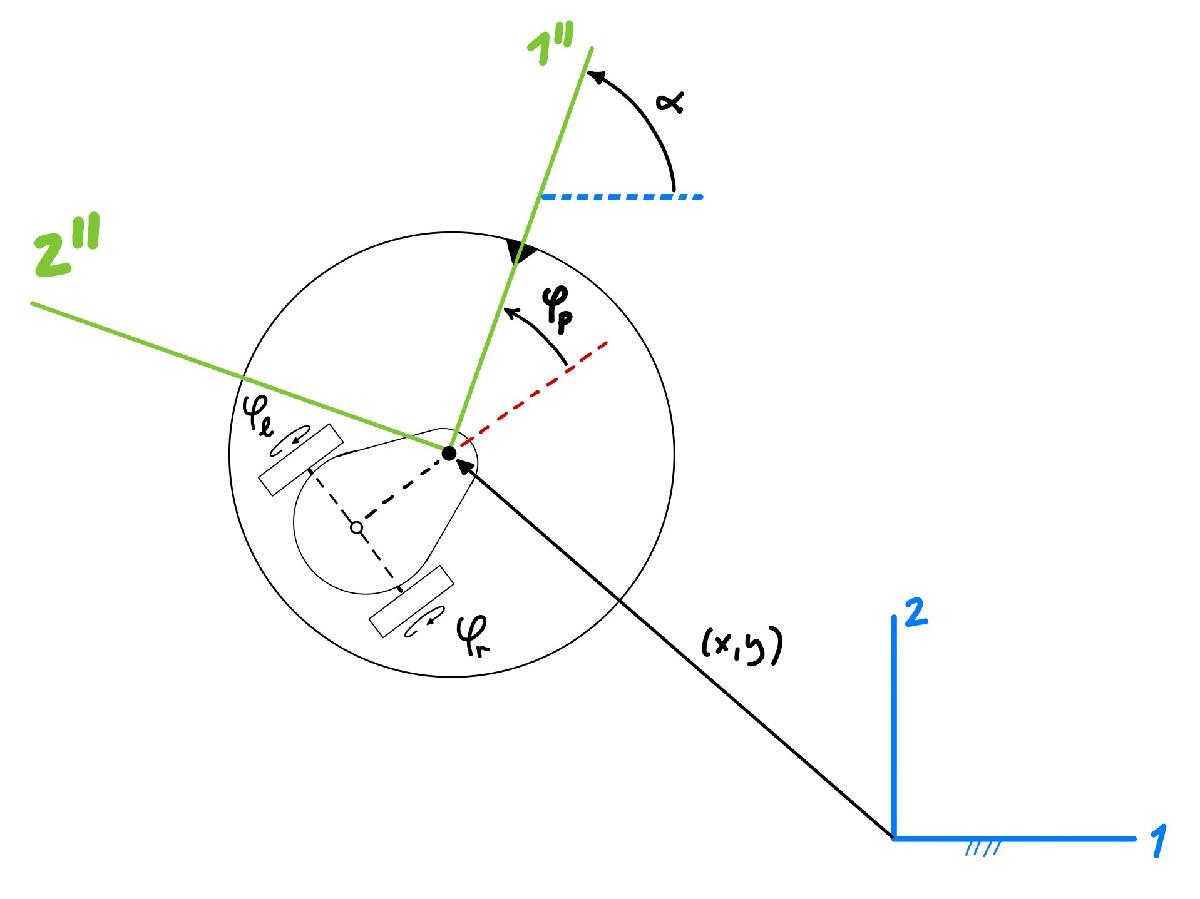

The robot configuration is thus given by

    
$$\mathbf{q} = (x,y,\alpha, \varphi_r,\varphi_l,\varphi_p)$$


and the time derivative of $\mathbf{q}$ provides the robot velocity

    
$$\dot{\mathbf{q}} = (\dot{x},\dot{y},\dot{\alpha}, \dot{\varphi_r},\dot{\varphi_l},\dot{\varphi_p})$$


Therefore, the robot state will be given by

    
$$\mathbf{x} = (\mathbf{q},\dot{\mathbf{q}})$$


## Kinematic constraints imposed by the rolling contacts

We will see that the coordinates of $\mathbf{x}$ are not independent. The rolling contacts of the wheels impose a kinematic constraint of the form 

    
$$\mathbf{J}(\mathbf{q}) \cdot \dot{\mathbf{q}} = \mathbf{0} $$


where $\mathbf{J}(\mathbf{q})$ is a $3 \times 6$ Jacobian matrix. We derive such a constraint in two steps: 

- We obtain the kinematic constraints imposed by the wheels.

- We rewrite these constraints using the $\mathbf{x}$ variables only.

We next see these steps in detail. On our derivations, we use $\mathbf{v}(Q)$ to denote the velocity of a point $Q$ of the robot. The basis in which $\mathbf{v}(Q)$ is expressed will be mentioned explicitly, or understood by context.

### Kinematic constraints of the differential drive

For the moment, let us neglect the platform and focus our attention on the chassis:

    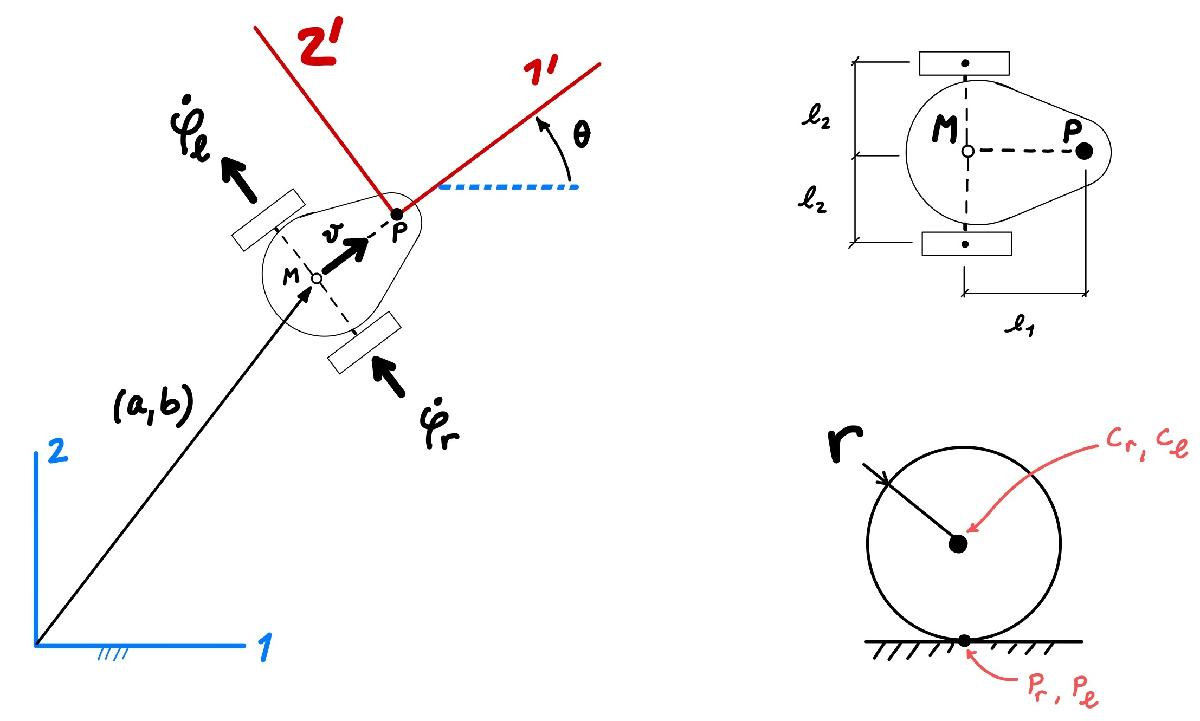        

The chassis pose is given by the position vector$(a,b)$of point M, and by the orientation angle $\theta$. M is the midpoint of the wheels axis, and P is the location of the pivot joint. We use $l_1$ and $l_2$ to refer to the pivot offset from M and the half-length of the wheels axis, respectively. Also, $C_r$ and $C_l$ denote the centers of the right and left wheels, and $P_r$ and $P_l$ are the contact points of such wheels with the ground. The two wheels have the same radius $r$.

The rolling contact constraints of the chassis can be found by computing the velocities of $\mathbf{v}(P_r)$ and $\mathbf{v}(P_l)$ in terms of $\dot{a}$, $\dot{b}$, $\dot{\theta}$, $\dot{\varphi_r}$, and $\dot{\varphi_l}$ (i.e., as if the robot were a floating kinematic tree) and forcing these velocities to be zero (as the wheels do not slide when placed on the ground). 

To obtain $\mathbf{v}(P_r)$ and $\mathbf{v}(P_l)$, note first that the velocity of $M$ can only be directed along axis 1', since lateral slipping is forbidden under perfect rolling. Therefore in B' = {1',2',3'}

    
$$\mathbf{v}(M) = 
\left\lbrack 
\begin{array}{c}
v \\
0 \\
0
\end{array}
\right\rbrack$$


Also note that,

    
$$\mathbf{v}(C_r) = \mathbf{v}(M) + \mathbf{\omega}_{\mathrm{chassis}} \times \overrightarrow{MC_r} = 
\left\lbrack 
\begin{array}{c}
v \\
0 \\
0
\end{array}
\right\rbrack
+
\left\lbrack 
\begin{array}{c}
0 \\
0 \\
\dot{\theta} 
\end{array}
\right\rbrack 
\times 
\left\lbrack 
\begin{array}{c}
0 \\
-l_2 \\
0
\end{array}
\right\rbrack
=
\left\lbrack 
\begin{array}{c}
v + l_2\;\dot{\theta} \\
0 \\
0
\end{array}
\right\rbrack
$$
    

    
$$\mathbf{v}(C_l) = 
\mathbf{v}(M) + \mathbf{\omega}_{\mathrm{chassis}} \times \overrightarrow{MC_l} = 
\left\lbrack 
\begin{array}{c}
v \\
0 \\
0
\end{array}
\right\rbrack
+
\left\lbrack 
\begin{array}{c}
0 \\
0 \\
\dot{\theta} 
\end{array}
\right\rbrack 
\times 
\left\lbrack 
\begin{array}{c}
0 \\
l_2 \\
0
\end{array}
\right\rbrack
=
\left\lbrack 
\begin{array}{c}
v-l_2\;\dot{\theta} \\
0 \\
0
\end{array}
\right\rbrack
$$


or, in Matlab syntax:

v_of_Cr = [v;0;0] + cross( [0;0;theta_dot], [0;-l_2;0] );  % Velocity of Cr
v_of_Cl = [v;0;0] + cross( [0;0;theta_dot], [0; l_2;0] );  % Velocity of Cl

The velocities of the ground contact points are thus given by

     
$$\mathbf{v}(P_r) =
\mathbf{v}(C_r) +
\mathbf{\omega}_{\text{wheel}} 
\times 
\overrightarrow{C_r P_r} 
= 
\left\lbrack 
\begin{array}{c}
v + l_2 \; \dot{\theta} \\
0 \\
0
\end{array}
\right\rbrack
+
\left\lbrack 
\begin{array}{c}
0 \\
\dot{\varphi}_r \\
\dot{\theta} 
\end{array}
\right\rbrack 
\times 
\left\lbrack 
\begin{array}{c}
0 \\
0 \\
-r
\end{array}
\right\rbrack
=
\left\lbrack 
\begin{array}{c}
v + l_2 \; \dot{\theta} - r \; \dot{\varphi}_r \\
0 \\
0
\end{array}
\right\rbrack

$$


     
$$\mathbf{v}(P_l) 

=

\mathbf{v}(C_l) + \mathbf{\omega}_{\mathrm{wheel}}  \times  \overrightarrow{C_l P_l} 

= 

\left\lbrack 
\begin{array}{c}
v - l_2 \; \dot{\theta} \\
0 \\
0
\end{array}
\right\rbrack

+

\left\lbrack 
\begin{array}{c}
0 \\
\dot{\varphi}_l \\
\dot{\theta} 
\end{array}
\right\rbrack 

\times 

\left\lbrack 
\begin{array}{c}
0 \\
0 \\
-r
\end{array}
\right\rbrack

=

\left\lbrack 
\begin{array}{c}
v - l_2 \; \dot{\theta} - r \; \dot{\varphi}_l \\
0 \\
0
\end{array}
\right\rbrack
$$


i.e.,

v_of_Pr = v_of_Cr + cross( [0; varphi_dot_r; theta_dot], [0; 0; -r]);  % Velocity of Pr
v_of_Pl = v_of_Cl + cross( [0; varphi_dot_l; theta_dot], [0; 0; -r]);  % Velocity of Pl

Since $P_r$ and $P_l$ do not slip, $\mathbf{v}(P_r)$ and $ \mathbf{v}(P_l)$ must be zero, which gives the two fundamental constraints of the robot:

eqn1 = (v_of_Pr(1) == 0);       
eqn2 = (v_of_Pl(1) == 0);
disp(eqn1); disp(eqn2);

$$v+l_{2}\,\dot{\theta }-r\,{\dot{\phi }}_{r}=0$$

$$v-l_{2}\,\dot{\theta }-r\,{\dot{\phi }}_{l}=0$$

It is now easy to solve for $v$ and $\dot{\theta}$ in these two equations:

[solved_v,solved_thetadot] = solve([eqn1,eqn2],[v,theta_dot]);

eqn3 = (v==simplify(solved_v));                  
eqn4 = (theta_dot==simplify(solved_thetadot));

disp(eqn3); disp(eqn4);

$$v=\frac{r\,\left({\dot{\phi }}_{l}+{\dot{\phi }}_{r}\right)}{2}$$

$$\dot{\theta }=-\frac{r\,\left({\dot{\phi }}_{l}-{\dot{\phi }}_{r}\right)}{2\,l_{2}}$$

Note from the previous figure that in the basis B = {1,2,3} 

    
$$\mathbf{v}(M) 

= 

\left\lbrack 
\begin{array}{c}
\dot{a} \\
\dot{b} \\
0
\end{array}
\right\rbrack
$$
 

and that it must be 

    
$$\left\lbrace
\begin{array}{l}
\dot{a} = v \cdot \cos{\theta} \\
\dot{b} = v \cdot \sin{\theta}
\end{array}
\right.$$


By substituting $v=\frac{r\,{\left({\varphi^˙ }_l +{\varphi^˙ }_r \right)}}{2}$ in these two equations, and also considering $\theta^˙ =-\frac{r\,{\left({\varphi^˙ }_l -{\varphi^˙ }_r \right)}}{2\,l_2 }$, we obtain the system:

eqn5 = a_dot == solved_v * cos(theta);
eqn6 = b_dot == solved_v * sin(theta);
eqn7 = eqn4;

disp(eqn5); disp(eqn6); disp(eqn7);

$$\dot{a}=\cos\left(\theta \right)\,\left(\frac{r\,{\dot{\phi }}_{l}}{2}+\frac{r\,{\dot{\phi }}_{r}}{2}\right)$$

$$\dot{b}=\sin\left(\theta \right)\,\left(\frac{r\,{\dot{\phi }}_{l}}{2}+\frac{r\,{\dot{\phi }}_{r}}{2}\right)$$

$$\dot{\theta }=-\frac{r\,\left({\dot{\phi }}_{l}-{\dot{\phi }}_{r}\right)}{2\,l_{2}}$$

This system provides the forward kinematic solution for the differential drive. It can also be viewed as the system of kinematic constraints that express the rolling contact constraints.

### Kinematic constraints of the whole robot

To obtain the kinematic constraints of Otbot itself, we just need to rewrite the previous system using the variables in $\mathbf{x}$. This entails substituting $\theta$, $\dot{\theta}$, $\dot{a}$, and $\dot{b}$ by their expressions in terms of the coordinates in $\mathbf{x}$. 

By looking at the figure

        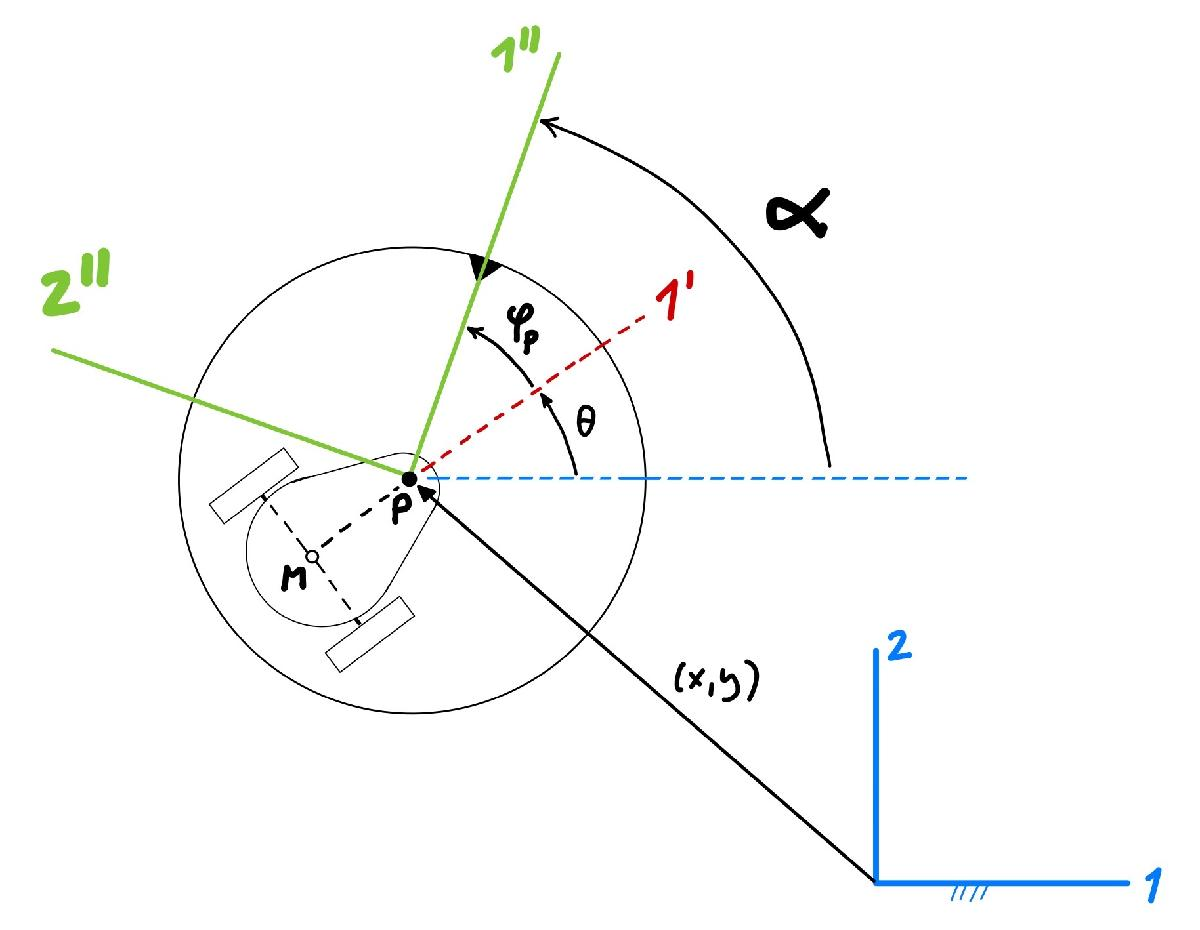

it is clear that 

    
$$\theta =\alpha -\varphi_p$$


    
$$\theta^˙ =\alpha^˙ -{\varphi^˙ }_p$$


and we also see that 

    $\mathbf{v}(M) = \mathbf{v}(P) + \omega_{\mathrm{chassis}} \times \overrightarrow{PM}$, 

so using B = {1, 2, 3} we can write

    
$$\left\lbrack 
\begin{array}{c}
\dot{a} \\
\dot{b} \\
0
\end{array}
\right\rbrack
=
\left\lbrack 
\begin{array}{c}
\dot{x} \\
\dot{y} \\
0
\end{array}
\right\rbrack
+
\left\lbrack 
\begin{array}{c}
0 \\
0 \\
\dot{\theta} 
\end{array}
\right\rbrack 
\times 
\left\lbrack 
\begin{array}{c}
-l_1 \cdot \cos{\theta} \\
-l_1 \cdot \sin{\theta} \\
0
\end{array}
\right\rbrack
=
\left\lbrack 
\begin{array}{c}
\dot{x} + \dot{\theta} \; l_1 \sin{\theta} \\
\dot{y} - \dot{\theta} \; l_1 \cos{\theta} \\
0
\end{array}
\right\rbrack
=
\left\lbrack 
\begin{array}{c}
\dot{x} + (\dot{\alpha}-\dot{\varphi}_p) \; l_1 \; \sin{(\alpha-\varphi_p)} \\
\dot{y} - (\dot{\alpha}-\dot{\varphi}_p) \; l_1 \; \cos{(\alpha-\varphi_p)} \\
0
\end{array}
\right\rbrack
$$


In sum we have the relationships

    
$$\left\lbrace
\begin{array}{l}
\theta = \alpha - \varphi_p \\
\dot{\theta} = \dot{\alpha} - \dot{\varphi}_p \\
\dot{a} = \dot{x} + (\dot{\alpha}-\dot{\varphi}_p) \; l_1 \; \sin{(\alpha-\varphi_p)} \\
\dot{b} = \dot{y} - (\dot{\alpha}-\dot{\varphi}_p) \; l_1 \; \cos{(\alpha-\varphi_p)} 
\end{array}
\right.$$


which give the desired values of  $\theta$, $\dot{\theta}$, $\dot{a}$, and $\dot{b}$ in terms of $\mathbf{q}$ and $\dot{\mathbf{q}}$. We thus can substitute these expressions in eqn5, eqn6, and eqn7 above to obtain eqn8, eqn9, and eqn10:

theta_value     = alpha - varphi_p;
theta_dot_value = alpha_dot - varphi_dot_p;
a_dot_value     = x_dot + (alpha_dot - varphi_dot_p) * l_1 * sin(alpha-varphi_p);
b_dot_value     = y_dot - (alpha_dot - varphi_dot_p) * l_1 * cos(alpha-varphi_p);

eqn8 = subs(eqn5,[a_dot,theta],[a_dot_value,theta_value]);
eqn9 = subs(eqn6,[b_dot,theta],[b_dot_value,theta_value]);
eqn10 = subs(eqn7,theta_dot,theta_dot_value);

disp(eqn8); disp(eqn9); disp(eqn10);

$$\dot{x}+l_{1}\,\sin\left(\alpha -\phi_{p}\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)=\cos\left(\alpha -\phi_{p}\right)\,\left(\frac{r\,{\dot{\phi }}_{l}}{2}+\frac{r\,{\dot{\phi }}_{r}}{2}\right)$$

$$\dot{y}-l_{1}\,\cos\left(\alpha -\phi_{p}\right)\,\left(\dot{\alpha }-{\dot{\phi }}_{p}\right)=\sin\left(\alpha -\phi_{p}\right)\,\left(\frac{r\,{\dot{\phi }}_{l}}{2}+\frac{r\,{\dot{\phi }}_{r}}{2}\right)$$

$$\dot{\alpha }-{\dot{\phi }}_{p}=-\frac{r\,\left({\dot{\phi }}_{l}-{\dot{\phi }}_{r}\right)}{2\,l_{2}}$$

In matrix form, these equations can be written as

            $\mathbf{J}\left(\mathbf{q}\right)\cdot \left\lbrack \begin{array}{c}
\dot{\;x} \\
\dot{y} \\
\dot{\alpha} \\
\dot{\varphi_r } \\
\dot{\varphi_l } \\
\dot{\varphi_p } 
\end{array}\right\rbrack$= **0**,

where $\mathbf{J}(\mathbf{q})$ is the $3 \times 6$ matrix

J_of_q = equationsToMatrix(...
    [eqn8,eqn9,eqn10],...
    [x_dot,y_dot,alpha_dot,varphi_dot_r,varphi_dot_l,varphi_dot_p])

$$J\_of\_q = \left[\begin{array}{cccccc} 1 & 0 & l_{1}\,\sin\left(\alpha -\phi_{p}\right) & -\frac{r\,\cos\left(\alpha -\phi_{p}\right)}{2} & -\frac{r\,\cos\left(\alpha -\phi_{p}\right)}{2} & -l_{1}\,\sin\left(\alpha -\phi_{p}\right)\\ 0 & 1 & -l_{1}\,\cos\left(\alpha -\phi_{p}\right) & -\frac{r\,\sin\left(\alpha -\phi_{p}\right)}{2} & -\frac{r\,\sin\left(\alpha -\phi_{p}\right)}{2} & l_{1}\,\cos\left(\alpha -\phi_{p}\right)\\ 0 & 0 & 1 & -\frac{r}{2\,l_{2}} & \frac{r}{2\,l_{2}} & -1 \end{array}\right]$$

## Solution to the instantaneous kinematic problems

Let $\mathbf{p}=(x,y,\alpha)$ and $\mathbf{\varphi} = (\varphi_r,\varphi_l,\varphi_p) $. These vectors provide the task and joint space variables of the robot. Their time derivatives $\dot{\mathbf{\varphi}}$ and $\dot{\mathbf{p}}$ are called the motor speeds and the platform twist, respectively

This section solves the following two problems:

- The forward instantaneous kinematic problem (**FIIKP**): Obtain $\dot{\mathbf{p}}$ as a function of $\dot{\mathbf{\varphi}}$.

- The inverse instantaneous kinematic problem (**IIKP**): Obtain $\dot{\mathbf{\varphi}}$ as a function of $\dot{\mathbf{p}}$.

It is also shown that the IIKP is always solvable, irrespective of the robot configuration. This implies that Otbot's platform can move omnidirectionally in the plane.

### Forward problem

We only have to isolate $\dot{x}$, $\dot{y}$, and $\dot{\alpha}
$ from the earlier equations eqn8, eqn9, and eqn10 defining $\mathbf{J}(\mathbf{q}) \cdot \dot{\mathbf{q}} = \mathbf{0} $:

[solved_xdot, solved_ydot, solved_alphadot] = solve([eqn8,eqn9,eqn10],[x_dot,y_dot,alpha_dot]);

eqn11 = (x_dot == solved_xdot);
eqn12 = (y_dot == solved_ydot);
eqn13 = (alpha_dot == solved_alphadot);

disp(eqn11); disp(eqn12); disp(eqn13); 

$$\dot{x}=\frac{l_{2}\,r\,{\dot{\phi }}_{l}\,\cos\left(\alpha -\phi_{p}\right)+l_{2}\,r\,{\dot{\phi }}_{r}\,\cos\left(\alpha -\phi_{p}\right)+l_{1}\,r\,{\dot{\phi }}_{l}\,\sin\left(\alpha -\phi_{p}\right)-l_{1}\,r\,{\dot{\phi }}_{r}\,\sin\left(\alpha -\phi_{p}\right)}{2\,l_{2}}$$

$$\dot{y}=\frac{l_{1}\,r\,{\dot{\phi }}_{r}\,\cos\left(\alpha -\phi_{p}\right)-l_{1}\,r\,{\dot{\phi }}_{l}\,\cos\left(\alpha -\phi_{p}\right)+l_{2}\,r\,{\dot{\phi }}_{l}\,\sin\left(\alpha -\phi_{p}\right)+l_{2}\,r\,{\dot{\phi }}_{r}\,\sin\left(\alpha -\phi_{p}\right)}{2\,l_{2}}$$

$$\dot{\alpha }=\frac{2\,l_{2}\,{\dot{\phi }}_{p}-r\,{\dot{\phi }}_{l}+r\,{\dot{\phi }}_{r}}{2\,l_{2}}$$

These equations directly provide $\dot{\mathbf{p}}$ as a function of $\dot{\mathbf{\varphi}}$. This function can be expressed as

    $\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{\alpha} 
\end{array}\right\rbrack = 
\mathbf{M}_{FIK}(\mathbf{q})
\cdot
\left\lbrack 
\begin{array}{c}
{\varphi^˙ }_r \\
{\varphi^˙ }_l \\
{\varphi^˙ }_p 
\end{array}
\right\rbrack
$,

where $\mathbf{M}_{FIK}(\mathbf{q})$ is the following $3 \times 3$ matrix:

MFIK_of_q = equationsToMatrix([solved_xdot, solved_ydot, solved_alphadot],...
                         [varphi_dot_r, varphi_dot_l, varphi_dot_p])

$$MFIK\_of\_q = \left[\begin{array}{ccc} \frac{l_{2}\,r\,\cos\left(\alpha -\phi_{p}\right)-l_{1}\,r\,\sin\left(\alpha -\phi_{p}\right)}{2\,l_{2}} & \frac{l_{2}\,r\,\cos\left(\alpha -\phi_{p}\right)+l_{1}\,r\,\sin\left(\alpha -\phi_{p}\right)}{2\,l_{2}} & 0\\ \frac{l_{1}\,r\,\cos\left(\alpha -\phi_{p}\right)+l_{2}\,r\,\sin\left(\alpha -\phi_{p}\right)}{2\,l_{2}} & -\frac{l_{1}\,r\,\cos\left(\alpha -\phi_{p}\right)-l_{2}\,r\,\sin\left(\alpha -\phi_{p}\right)}{2\,l_{2}} & 0\\ \frac{r}{2\,l_{2}} & -\frac{r}{2\,l_{2}} & 1 \end{array}\right]$$

### Inverse problem

We now wish to find $\dot{\mathbf{\varphi}}$ as a function of $\dot{\mathbf{p}}$.  Clearly, this function is given by

    $\left\lbrack 
\begin{array}{c}
{\varphi^˙ }_r \\
{\varphi^˙ }_l \\
{\varphi^˙ }_p 
\end{array}
\right\rbrack


= 

\mathbf{M}_{IIK}(\mathbf{q})

\cdot

\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{\alpha} 
\end{array}\right\rbrack 
$,

where $\mathbf{M}_{IIK}(\mathbf{q})
= 
\mathbf{M}_{FIK}^{-1}(\mathbf{q})$. 

Note that the determinant of $\mathbf{M}_{FIK}(\mathbf{q})$ is

detMFIK = simplify(det(MFIK_of_q))

$$detMFIK = -\frac{l_{1}\,r^{2}}{2\,l_{2}}$$

Since $r
$, $l_1$, and $l_2$ are all positive in Otbot, we see that $\mathbf{M}_{FIK}^{-1}(\mathbf{q})$ always exists, so the IIKP is solvable in all configurations of the robot. An important consequence is that the platform will be able to move under any twist $\dot{\mathbf{p}}$ in the plane. In other words, it will be an omnidirectional platform.

$\mathbf{M}_{IIK}(\mathbf{q})$ has the expression:

MIIK_of_q = simplify(inv(MFIK_of_q))

$$MIIK\_of\_q = \left[\begin{array}{ccc} \frac{l_{1}\,\cos\left(\alpha -\phi_{p}\right)-l_{2}\,\sin\left(\alpha -\phi_{p}\right)}{l_{1}\,r} & \frac{l_{2}\,\cos\left(\alpha -\phi_{p}\right)+l_{1}\,\sin\left(\alpha -\phi_{p}\right)}{l_{1}\,r} & 0\\ \frac{l_{1}\,\cos\left(\alpha -\phi_{p}\right)+l_{2}\,\sin\left(\alpha -\phi_{p}\right)}{l_{1}\,r} & -\frac{l_{2}\,\cos\left(\alpha -\phi_{p}\right)-l_{1}\,\sin\left(\alpha -\phi_{p}\right)}{l_{1}\,r} & 0\\ \frac{\sin\left(\alpha -\phi_{p}\right)}{l_{1}} & -\frac{\cos\left(\alpha -\phi_{p}\right)}{l_{1}} & 1 \end{array}\right]$$

## The kinematic model in control form

These equations

    
$$\left\lbrace 
\begin{array}{l}
\dot{\mathbf{p}} = 
\mathbf{M}_{FIK}(\mathbf{q}) 
\cdot
\dot{\mathbf{\varphi}} 
\\
\dot{\mathbf{\varphi}} = \dot{\mathbf{\varphi}} 
\end{array}
\right.$$


can be written in the usual form used in control engineering,

    $\dot{\mathbf{q}} 
=
\mathbf{f}_{\mathrm{kin}}(\mathbf{q},\mathbf{v})$,

where $\mathbf{v} = \dot{\mathbf{\varphi}}$ and 

    $\mathbf{f}_{\mathrm{kin}}(\mathbf{q},\mathbf{v}) = \left\lbrack \begin{array}{c}
\mathbf{M}_\mathrm{FIK}(\mathbf{q}) \\
\mathbf{I}_{3}
\end{array}\right\rbrack \cdot \dot{\mathbf{\varphi}}$. 

Notice that in this model $\mathbf{v} $ plays the role of the control actions, which are motor velocities in this case. 

We could use this model for trajectory planning already. In doing so, we would neglect the system dynamics, but a strong point is the model simplicity, which leads to faster planners and controllers. Moreover, the model would be sufficient if the commanded velocities $\mathbf{v}(t)$ where easy to control (e.g., if $\mathbf{v}(t)$ is smooth enough for the motors at hand). The model would also be helpful to perform early tests of a planner under development, or to compute approximate trajectories to be later enhanced by an optimizer (one using the full dynamical model for example).

## Save matrices 

save('forward_inverse_jacobians.mat',"MIIK_of_q","MFIK_of_q")
save('constraint_jacobian.mat',"J_of_q")

## Print ellapsed time

toc

Elapsed time is 1.483650 seconds.
